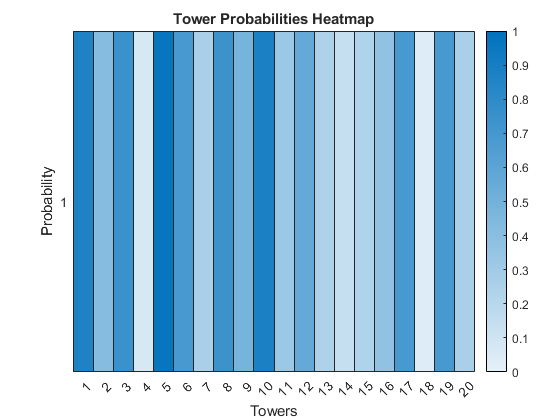

% Define the parameters
clc; clear;
numAnts = 4;
numIterations = 1;
alpha = 1;   % Pheromone importance
beta = 3;    % Prob importance
evaporationRate = 0.85;

% Generate random tower positions and probabilities
numTowers = 20;
towerProbabilities = rand(numTowers, 1);

% Reshape the array for the heatmap
heatmapData = reshape(towerProbabilities, 1, []);

% Plot the heatmap
figure;
heatmap(heatmapData, 'ColorLimits', [0, 1], ...
    'XLabel', 'Towers', 'YLabel', 'Probability', 'Title', 'Tower Probabilities Heatmap');

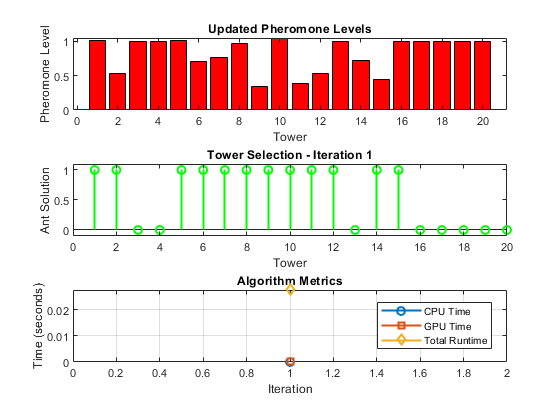

Iteration 1: Average Probability = 0.5578


Runtime for iteration 1: 0.0277 seconds



% Define problem-specific parameters
k = 20;    % Number of TLAs to install
minConsecutiveTLAs = 3;

% Initialize pheromone levels
pheromoneLevels = ones(numTowers, 1);

% Initialize the best solution and its probability
bestSolution = [];
minAvgProbability = 1;

% Initialize metrics arrays
cpuTime = zeros(numIterations, 1);
gpuTime = zeros(numIterations, 1);
runtimes = zeros(numIterations, 1);

% Create a new figure for the GIF
gifFigure = figure;

% Initialize GIF frame
gifData = [];

% Create a new figure for the video
videoFigure = figure;

% Initialize VideoWriter
videoFile = VideoWriter('animation.mp4', 'MPEG-4');
open(videoFile);

for iteration = 1:numIterations
    tic;
    antSolutions = cell(numAnts, 1); % Empty array
    antProbabilities = zeros(numAnts, 1);

    for ant = 1:numAnts
        visited = false(numTowers, 1); % Logical zeros
        antSolution = zeros(k, 1); % TLAs install index, black = 1, white = 0

        % Construct the solution
        for tower = 1:numTowers
            % Calculate probabilities for unvisited towers using pheromones
            unvisitedIndices = find(~visited);
            probabilities = (pheromoneLevels(unvisitedIndices) .^ alpha) .* (towerProbabilities(unvisitedIndices) .^ beta);
            probabilities = probabilities / sum(probabilities);

            % Choose tower with pheromone-based probability
            chosenTower = chooseWithProbability(probabilities, pheromoneLevels, alpha, beta);

            if ~isempty(chosenTower)
                % Update the antSolution and visited array
                antSolution = installTLAs(chosenTower, antSolution, k, minConsecutiveTLAs);
                visited(chosenTower) = true;
            end
        end

        antSolutions{ant} = antSolution;
        antProbabilities(ant) = mean(towerProbabilities(antSolution(antSolution <= numTowers)));
    end

    % Update pheromone levels based on the best ant solution
    [~, bestAnt] = min(antProbabilities);
    bestAntSolution = antSolutions{bestAnt};
    
    for i = 1:numel(bestAntSolution) - minConsecutiveTLAs + 1
        subSolution = bestAntSolution(i:i + minConsecutiveTLAs - 1);
        if max(subSolution) <= numel(pheromoneLevels)
            avgProbability = mean(towerProbabilities(subSolution));
            pheromoneLevels(subSolution) = (1 - evaporationRate) * pheromoneLevels(subSolution) + avgProbability;
        end
    end

    % Update the best solution if a better one is found
    if antProbabilities(bestAnt) < minAvgProbability
        bestSolution = bestAntSolution;
        minAvgProbability = antProbabilities(bestAnt);
    end

    % Display the best solution in this iteration
    fprintf('Iteration %d: Average Probability = %.4f\n', iteration, antProbabilities(bestAnt));
    
    % Measure and display runtime
    runtime = toc;
    fprintf('Runtime for iteration %d: %.4f seconds\n', iteration, runtime);
    runtimes(iteration) = runtime;

    % Plot the updated pheromone levels
    subplot(3, 1, 1);
    bar(1:numTowers, pheromoneLevels, 'r');
    title('Updated Pheromone Levels');
    xlabel('Tower');
    ylabel('Pheromone Level');

    % Pause for visualization (adjust as needed)
    pause(1);
    
    % Plot the tower selection for the best ant
    subplot(3, 1, 2);
    plotAntSolution(bestAntSolution, numTowers);
    title(['Tower Selection - Iteration ' num2str(iteration)]);
    xlabel('Tower');
    ylabel('Ant Solution');

    % Pause for visualization (adjust as needed)
    pause(1);
    
    % Plot metrics
    subplot(3, 1, 3);
    plotMetrics(cpuTime, gpuTime, runtimes, iteration);
    
%     % Save the frame to the GIF file
%     gifFrame = getframe(gifFigure);
%     frameData = gifFrame.cdata;
%     [frameData, ~] = rgb2ind(frameData, 256);
%     
%     if iteration == 1
%         imwrite(frameData, 'animation.gif', 'gif', 'LoopCount', Inf, 'DelayTime', 1);
%     else
%         imwrite(frameData, 'animation.gif', 'gif', 'WriteMode', 'append', 'DelayTime', 1);
%     end
% 
%     % Save the frame to the video file
%     writeVideo(videoFile, getframe(videoFigure));
    
end


% Close VideoWriter
close(videoFile);


% Display the final best solution and its average probability
fprintf('Final Best Solution:\n');

Final Best Solution:


fprintf('Average Probability = %.4f\n', minAvgProbability);

Average Probability = 0.5578


fprintf('TLA Positions = %s\n', mat2str(sort(bestSolution)));

TLA Positions = [1;1;1;2;5;5;5;6;7;7;7;8;9;10;11;11;12;14;14;15]



% Calculate total runtime
totalRuntime = sum(runtimes);

% Display metrics
fprintf('Total Runtime: %.4f seconds\n', totalRuntime);

Total Runtime: 0.0277 seconds


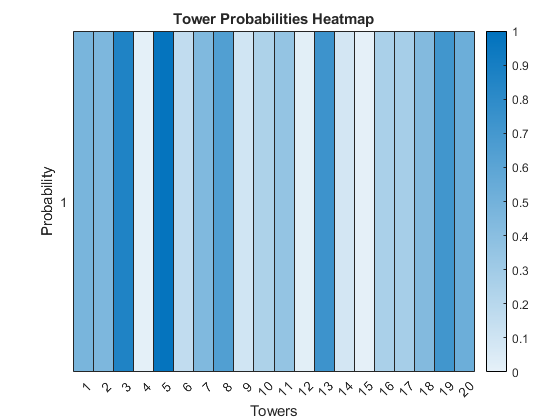

Iteration 1: Min Average Probability = 0.3462


CPU Time: 0.0000 seconds


GPU Time: 0.0000 seconds


Total Runtime: 2.1119 seconds



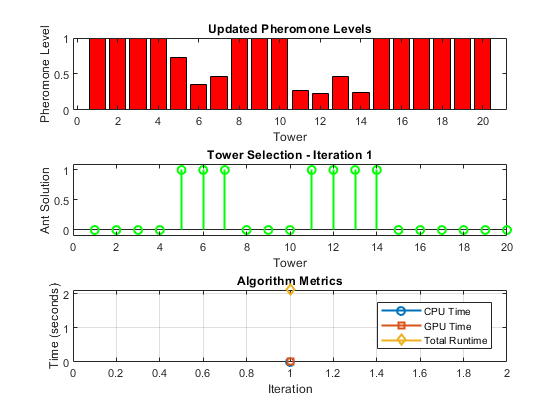

Error using guidata (line 77)
Not enough input arguments.

function antSolution = installTLAs(tower, antSolution, k, minConsecutiveTLAs)

    % Find indices of uninstalled TLAs
    not_installed = find(~antSolution);

    % Calculate the number of TLAs already installed
    sumNonZero = sum(antSolution ~= 0);

    % Calculate the remaining TLAs to install
    k_remain = k - sumNonZero; % sumNonZero = total installed TLAs

    if k_remain >= minConsecutiveTLAs
        % Find consecutive available positions to install minConsecutiveTLAs TLAs
        start_idx = find(diff([0; not_installed]) == 1);
        end_idx = start_idx + minConsecutiveTLAs - 1;

        % Ensure end_idx does not exceed the available positions
        end_idx(end_idx > length(not_installed)) = length(not_installed);

        % Check for redundancy, overlap, non-consecutive installation, and discard the solution if found
        while any(ismember(antSolution(not_installed(start_idx:end_idx)), antSolution(antSolution ~= 0))) || ...
              any(ismember(antSolution(not_installed(start_idx:end_idx)), antSolution(antSolution > 0))) || ...
              any(diff(antSolution(not_installed(start_idx:end_idx))) <= 0) || ...
              any(diff(not_installed(start_idx:end_idx)) ~= 1) || ...
              any(diff(antSolution(not_installed(start_idx:end_idx))) == 0) || ...
              any(diff(not_installed(start_idx:end_idx)) == 0) || ...
              any(histcounts(antSolution(not_installed(start_idx:end_idx)), 'BinMethod', 'integers') > 1)
            % If redundancy, overlap, non-consecutive installation, or consecutive installation is found, shift the installation by one position
            start_idx = start_idx + 1;
            end_idx = start_idx + minConsecutiveTLAs - 1;

            % Ensure end_idx does not exceed the available positions
            end_idx(end_idx > length(not_installed)) = length(not_installed);
        end

        % Install TLAs consecutively
        antSolution(not_installed(start_idx:end_idx)) = tower + (0:(end_idx - start_idx));
    else
        if k_remain > 0
            % If not enough space for minConsecutiveTLAs, install as many as possible
            minConsecutiveTLAs = k_remain;
        else
            % Print an error message (you can uncomment the line below if needed)
            % fprintf('Error: Not enough available positions to install %d TLAs.\n', k);

            % Return without modifying antSolution
            return;
        end

        % Update to handle the case when minConsecutiveTLAs > length(not_installed)
        end_idx = min(minConsecutiveTLAs, length(not_installed));

        % Check for redundancy, overlap, non-consecutive installation, and discard the solution if found
        while any(ismember(antSolution(not_installed(1:end_idx)), antSolution(antSolution ~= 0))) || ...
              any(ismember(antSolution(not_installed(1:end_idx)), antSolution(antSolution > 0))) || ...
              any(diff(antSolution(not_installed(1:end_idx))) <= 0) || ...
              any(diff(not_installed(1:end_idx)) ~= 1) || ...
              any(diff(antSolution(not_installed(1:end_idx))) == 0) || ...
              any(diff(not_installed(1:end_idx)) == 0) || ...
              any(histcounts(antSolution(not_installed(1:end_idx)), 'BinMethod', 'integers') > 1)
            % If redundancy, overlap, non-consecutive installation, or consecutive installation is found, shift the installation by one position
            end_idx = end_idx - 1;

            % Ensure end_idx does not exceed the available positions
            end_idx = min(end_idx, length(not_installed));
        end

        % Install TLAs up to end_idx
        antSolution(not_installed(1:end_idx)) = tower + (0:(end_idx - 1));
    end
end

function choice = chooseWithProbability(probabilities, pheromones, pheromoneImportance, beta)
    % Calculate probabilities for unvisited towers
    unvisitedIndices = find(probabilities > 0);
    probabilities = (pheromones(unvisitedIndices) .^ pheromoneImportance) .* (probabilities(unvisitedIndices) .^ beta);
    probabilities = probabilities / sum(probabilities);

    cumulativeProbabilities = cumsum(probabilities);
    if ~isempty(cumulativeProbabilities)
        randValue = rand() * cumulativeProbabilities(end);
        choice = unvisitedIndices(find(randValue <= cumulativeProbabilities, 1, 'first'));
    else
        % Handle the case when cumulativeProbabilities is empty
        choice = [];
    end
end


% Function to plot the tower selection for an ant solution
function plotAntSolution(antSolution, numTowers)
    antPlot = zeros(1, numTowers);
    indices = antSolution(antSolution ~= 0);
    
    % Ensure indices are within the correct range
    indices = max(1, min(numTowers, indices));
    
    antPlot(indices) = 1;
    stem(1:numTowers, antPlot, 'g', 'LineWidth', 1.5);
    ylim([-0.1, 1.1]);
end


function plotMetrics(cpuTime, gpuTime, runtimes, iteration)
    plot(1:iteration, cpuTime(1:iteration), '-o', 'LineWidth', 1.5, 'DisplayName', 'CPU Time');
    hold on;
    plot(1:iteration, gpuTime(1:iteration), '-s', 'LineWidth', 1.5, 'DisplayName', 'GPU Time');
    plot(1:iteration, runtimes(1:iteration), '-d', 'LineWidth', 1.5, 'DisplayName', 'Total Runtime');
    hold off;
    title('Algorithm Metrics');
    xlabel('Iteration');
    ylabel('Time (seconds)');
    legend('Location', 'Best');
    grid on;
    drawnow;
end
